clc
clear
A=[1.0041 0.01 0 0;
    0.8281 1.0041 0 -0.0093;
    0.0002 0.0000 1 0.0098;
    0.0491 0.0002 0 0.9626];
B = [0.0007;
     0.1398;
     0.0028;
     0.5605];
C = [1 0 0 0;
     0 0 1 0];
Bp = B;
Cp = [0;1];
p = size(C,1); % outputs 2
m = size(B,2); % inputs 2
n = size(A,1); % states 4
Mo = obsv(A,C);
rank(Mo)

ans = 4


% case 1, nd = 1
% nd = 1;
% Bd = zeros(4,1);
% Cd = [1;1];

% case 3, nd = 2
nd = 2;
Bd = [zeros(4,1) Bp]

Bd =          0    0.0007
         0    0.1398
         0    0.0028
         0    0.5605


Cd = eye(nd);


t = size(Bd,2);
Aa = [A, Bd;
      zeros(nd,n),  eye(t)]

Aa =     1.0041    0.0100         0         0         0    0.0007
    0.8281    1.0041         0   -0.0093         0    0.1398
    0.0002         0    1.0000    0.0098         0    0.0028
    0.0491    0.0002         0    0.9626         0    0.5605
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


Ba = [B;zeros(nd,m)]

Ba =     0.0007
    0.1398
    0.0028
    0.5605
         0
         0


Ca = [C Cd]

Ca =      1     0     0     0     1     0
     0     0     1     0     0     1


if(rank([eye(n)-A, -Bd;C, Cd])==(n+nd))
    disp("Augmented system is detectable")
else
    disp("not detectable")
end

Augmented system is detectable


b) Design a KF

Qn = eye(size(Aa));
Rn = eye(size(Ca,1));
P = idare(Aa',Ca',Qn,Rn);
L = P*Ca'*inv(Ca*P*Ca'+Rn)

L =     1.2496    0.0099
   10.4751    0.2570
    0.0111    0.2278
    0.2722    1.8728
   -0.4815   -0.0090
   -0.0102    0.5110



Q = eye(size(A));
R = eye(size(C,1));
P = idare(A',C',Q,R);
L = P*C'*inv(C*P*C'+R)

L =     0.6266    0.0000
    1.4008   -0.0063
    0.0000    0.6185
    0.0139    0.0765


c) Find steady-state target [xs;us]

H = [0 1];
M = [eye(n)-A -B;
     H*C, zeros(size(H*C,1),m)]

M =    -0.0041   -0.0100         0         0   -0.0007
   -0.8281   -0.0041         0    0.0093   -0.1398
   -0.0002         0         0   -0.0098   -0.0028
   -0.0491   -0.0002         0    0.0374   -0.5605
         0         0    1.0000         0         0


Mss = inv(M)*[Bd;-H*Cd]

Mss =          0    0.0000
         0    0.0000
         0   -1.0000
         0   -0.0000
         0   -1.0000


d) RHC design

Q=diag([5 2 0.5 0.1]);
R=0.1;
N=50;
M=40;
tf = 1000;
Pf=Q;
% initial state
x0 = [pi/36 0 0 0]';
% simulationed states sequence
xk = x0;
x_seq = zeros(4,tf);
x_seq(:,1) = x0;
uk_seq = zeros(1,tf);
yk_seq = zeros(2,tf);
% estimation states sequence
x_hat=[0;0;0;0];
eps_hat = [x_hat;zeros(nd,1)];
P_eps = 1*eye(6);
x_hat_seq = zeros(4,tf);
x_hat_seq(:,1) = x_hat;
% disturbance sequence
p = 0.2*ones(1,tf);
pos = 1:50;
p(pos) = 0;

% matrix for stationary setpoint calculation
H = [0 1];
M = [eye(n)-A -B;
     H*C, zeros(size(H*C,1),m)];
% output setpoint
ysp = 0;

for k=2:tf

    % Target selector
    d_hat = eps_hat(n+1:end);
    [xs,us] = TargetSelector(M,Bd,Cd,H,ysp,d_hat);
    delta_x = x_hat - xs;
    
    % RHC controller
    [Z,~] = A2URHC(A,B,N,Q,R,Pf,delta_x,n);
    delta_u = Z(size(A,1)*N+1);
    uk = delta_u+us;
    uk_seq(k) = uk;
    % Plant simulation
    [xk_1,yk] = plant(A,B,C,Bp,Cp,xk,uk,k);
    xk = xk_1;
    x_seq(:,k) = xk;
    yk_seq(:,k) = yk;
    % Observer
    [eps_hat, P_eps] = observer(Aa,Ba,Ca,eps_hat,P_eps,uk,yk,Qn,Rn);
    x_hat_seq(:,k) = eps_hat(1:n,1);
    x_hat = eps_hat(1:n,1);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

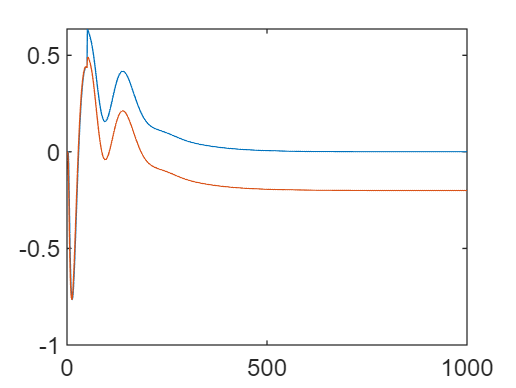

figure
plot(yk_seq(2,:))
hold on
plot(x_hat_seq(3,:))

function [xs,us] = TargetSelector(M,Bd,Cd,H,ysp,d_hat)
    P = [Bd*d_hat;ysp-H*Cd*d_hat];
    v = inv(M)*P;
    n = size(M,1)-size(d_hat,1);
%     MSS=[0 0 -1 0 0]';
    MSS=[0 0 0 0 0;0 0 -1 0 -1]';  
    Zs = MSS*d_hat;
    xs = Zs(1:4,:);
    us = Zs(5,:);
end

function [xk_1,yk] = plant(A,B,C,Bp,Cp,xk,uk,k)
    if(k<=50)
        p = 0;
    else
        p = 0.2;
    end

    xk_1 = A*xk + B*uk + Bp*p;
    yk = C*xk + Cp*p; 
end

function [eps_hat_1, Pk_1] = observer(Aa,Ba,Ca,eps_hat,P,uk,y,Qn,Rn)
% eps_hat: eps_hat(k|k-1)    
% P: P(k|k-1)
% uk: u(k)
% y: y(k)
%     [P,~]=idare(Aa',Ca',1,1); % solve the riccati for KF gain, noise are identity
    L = P*Ca'*inv(Ca*P*Ca' + Rn);
    % correction eps_hat(k|k)
    eps_hat = eps_hat + L*(y-Ca*eps_hat);
    Pk = P - L*Ca*P;
    % prediction eps_hat(k+1|k) = Aa*eps_hat(k|k)+Ba*u(k)
    eps_hat_1 = Aa*eps_hat + Ba*uk;
    Pk_1 = Aa*Pk*Aa' + Qn;
end
